addpath('D:\Amirali\EEGLAB\eeglab_current\eeglab2021.1')

## Pre-Processing Steps

In this step all processing steps have been done in EEGLAB framework. 

### Questions

#### (a)

The reason of high-pass filtering is to remove interference of channels on each other and the reason of notch filtering is to remove line noise from the data. As you know the frequency of line noise is harmonics of 50Hz. The showable effect of these filters can be figured in frequency domain of data. In this part at first we can see the spectogram of raw EEG given data below. 

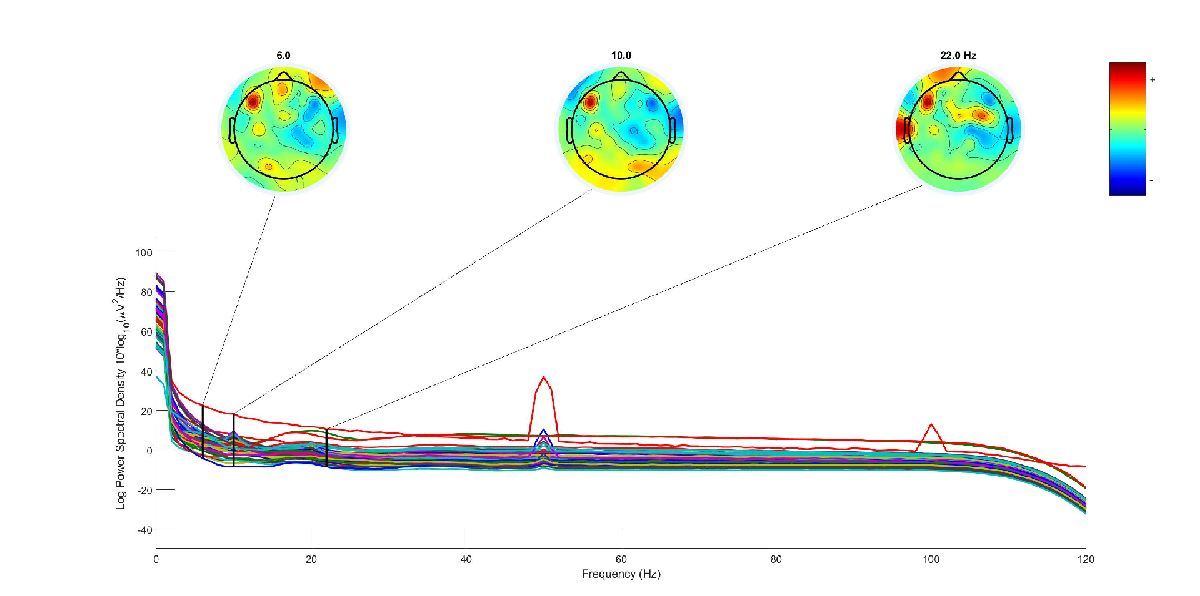

In next figure the effect of high-pass filtering can be shown. As shown in the figure the amplitude of frequencies after 0.1Hz has been decreased and they have lower value than before.

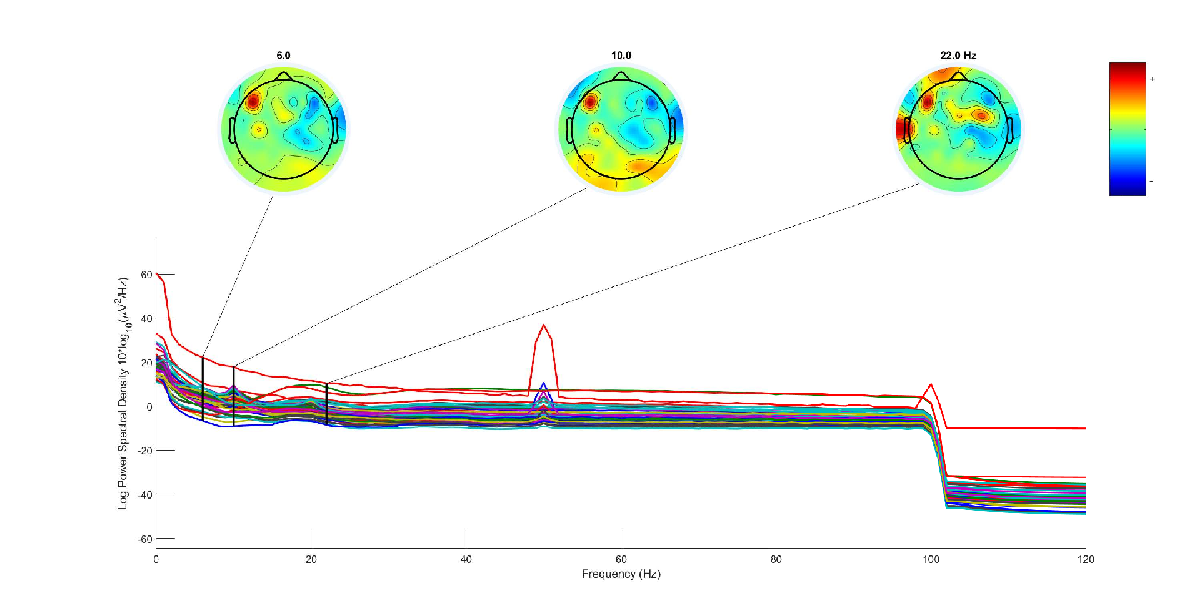

In next figure also can be shown that the notch filtering has been lowered the amplitude of 50 and 100Hz frequencies so that the level of this frequency is nearly equivalent to other frequencies.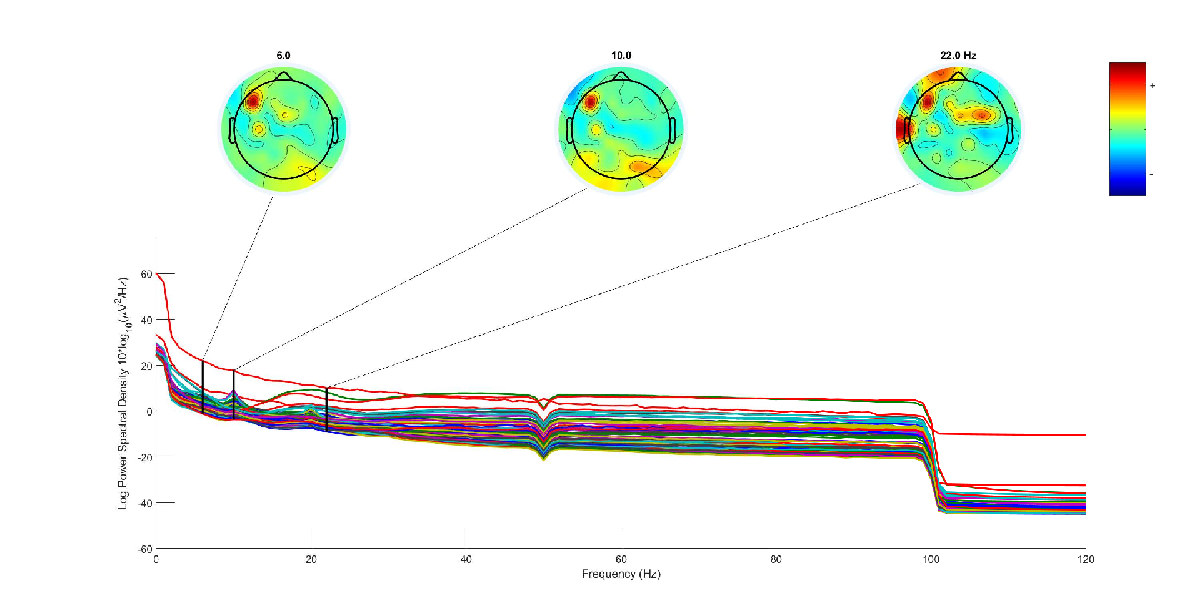

#### (b)

These noise removal steps are used in between channel or trial interferences. For example by epoching data we have post stimuli effects on next trial so we can remove this by baseline normalization. Or if some electrodes have bad effect or functionality we can remove this artifact by re-referencing the data. Also activity on the reference electrode can be projected to all other electrodes so re-referencing can remove this effect too.

#### (c) 

Event-Related Potentials (ERPs) for all channels can be shown in below figure. As shown in the figure some channels like PO6, PO4, and some other occipital channels has problems duo to have lots of negative values.

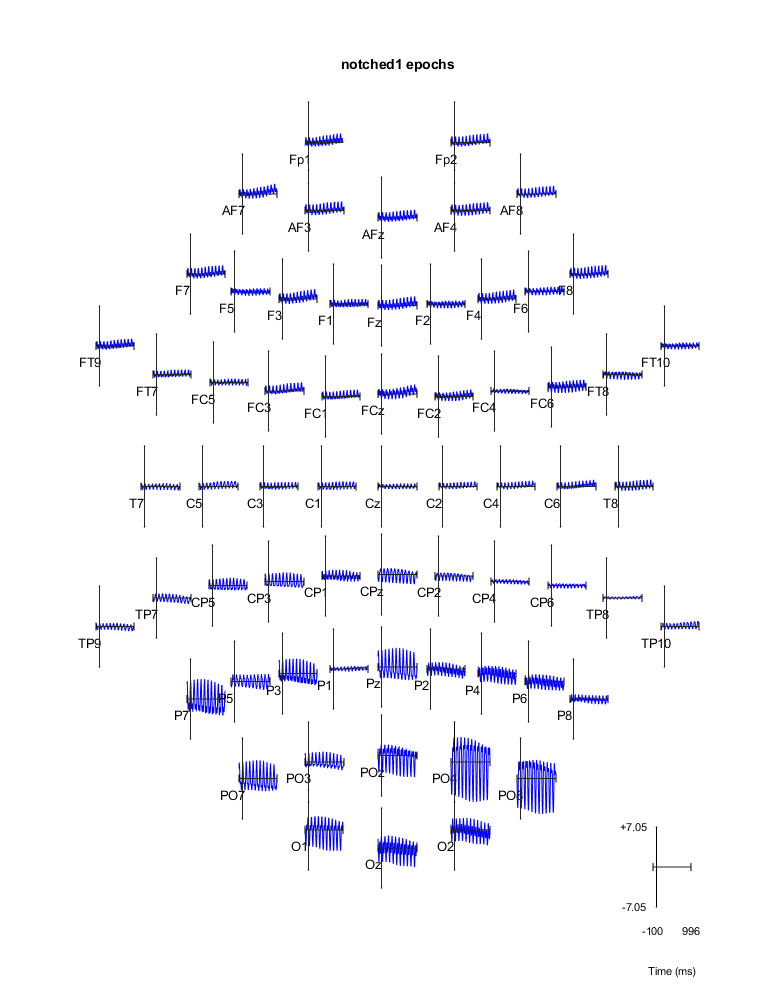

% Load Saved Data
epochedData = load('data/epochedData.mat');
epochedTime = load('data/epochedTime.mat');
epochedData = epochedData.epochedData;
epochedTime = epochedTime.epochedTime;
epochedData = double(epochedData);

## 1.2 Representational Dissimilarity Matrices (RDMs)

eventsData = readtable('data/events.csv');

## Create RDM

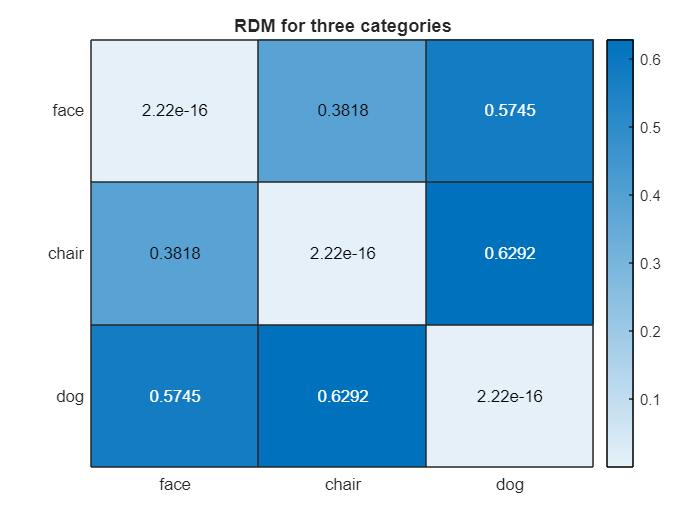

objects  = eventsData.object;
idxFace  = find(strcmp(objects, 'face'));
idxChair = find(strcmp(objects, 'chair'));
idxDog   = find(strcmp(objects, 'dog'));

meanTime = find(epochedTime < 225 & epochedTime > 175);

faceEEG  = epochedData(:, meanTime, idxFace);
chairEGG = epochedData(:, meanTime, idxChair);
dogEGG   = epochedData(:, meanTime, idxDog);

meanFace  = mean(mean(faceEEG, 3), 2);
meanChair = mean(mean(chairEGG, 3), 2);
meanDog   = mean(mean(dogEGG, 3), 2);

means  = [meanFace meanChair meanDog];
figure
RDM    = 1 - corr(means, means, 'Type', 'Spearman');
RDMMap = heatmap(RDM);
RDMMap.YDisplayLabels = {'face', 'chair', 'dog'};
RDMMap.XDisplayLabels = {'face', 'chair', 'dog'};
RDMMap.Title = 'RDM for three categories';

## RSA model

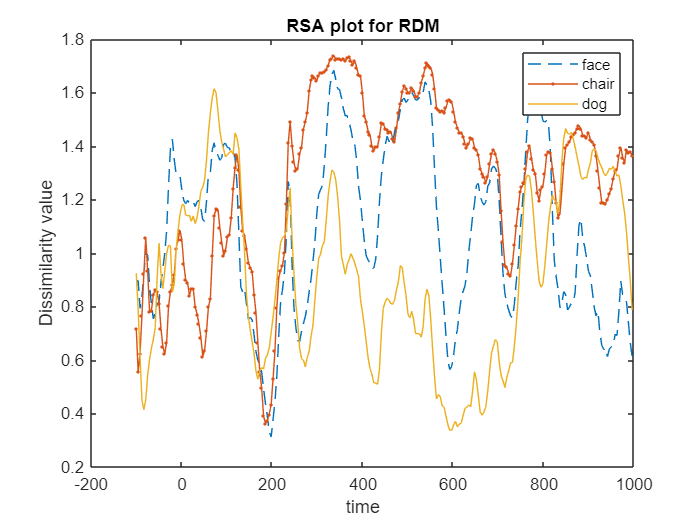

windowLength = find(epochedTime <= min(epochedTime) + 50 & epochedTime >= min(epochedTime));
faceRSA      = nan(1, length(epochedTime) - length(windowLength));
chairRSA     = nan(1, length(epochedTime) - length(windowLength));
dogRSA       = nan(1, length(epochedTime) - length(windowLength));
for i = 1:length(epochedTime) - length(windowLength)
    windowTime = windowLength + i - 1;
    faceEEG    = epochedData(:, windowTime, idxFace);
    chairEGG   = epochedData(:, windowTime, idxChair);
    dogEGG     = epochedData(:, windowTime, idxDog);
    meanFace   = mean(mean(faceEEG, 3), 2);
    meanChair  = mean(mean(chairEGG, 3), 2);
    meanDog    = mean(mean(dogEGG, 3), 2);
    meansFace  = [meanFace meanChair + meanDog];
    meansChair = [meanChair meanFace + meanDog];
    meansDog   = [meanDog meanFace + meanChair];
    faceCorr   = 1 - corr(meansFace, meansFace, 'Type', 'Spearman');
    chairCorr  = 1 - corr(meansChair, meansChair, 'Type', 'Spearman');
    dogCorr    = 1 - corr(meansDog, meansDog, 'Type', 'Spearman');
    faceRSA(i) = faceCorr(2);
    chairRSA(i)= chairCorr(2);
    dogRSA(i)  = dogCorr(2);
end

timeRSA = linspace(-100, (length(epochedTime) - length(windowLength))*4 - 52, length(epochedTime) - length(windowLength));
figure
plot(timeRSA, faceRSA, '--')
hold on
plot(timeRSA, chairRSA, '.-')
hold on
plot(timeRSA, dogRSA)
legend('face', 'chair', 'dog')
xlabel('time')
ylabel('Dissimilarity value')
title('RSA plot for RDM')

## Questions

### (a)

As shown above, the dissimilarity value in 200 ms between classes is not significant to see difference between classes. As instance I have chosen the time value which has maximum value in summation of all classes. When I chose this value the RDM became like below which can be figured that this time has better performance for dissimilarity between classes.

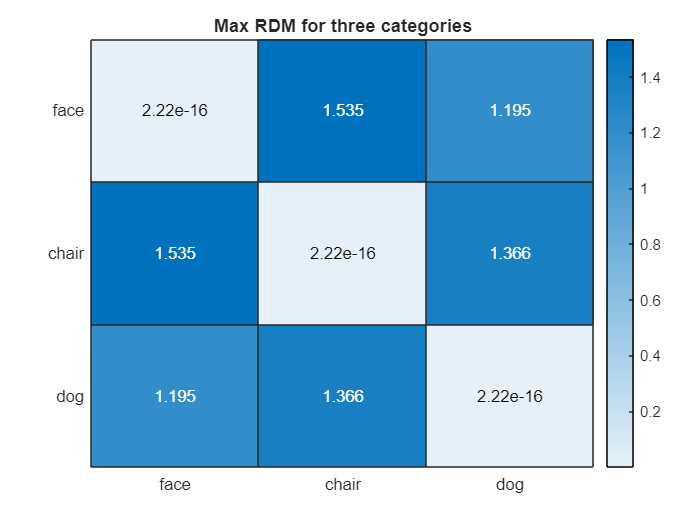

totalRSA     = faceRSA + chairRSA + dogRSA;
maxIdx       = find(totalRSA == max(totalRSA));
maxTime      = timeRSA(maxIdx);
meanInterval = find(epochedTime < maxTime + 25 & epochedTime > maxTime - 25);

faceEEG  = epochedData(:, meanInterval, idxFace);
chairEGG = epochedData(:, meanInterval, idxChair);
dogEGG   = epochedData(:, meanInterval, idxDog);

meanFace  = mean(mean(faceEEG, 3), 2);
meanChair = mean(mean(chairEGG, 3), 2);
meanDog   = mean(mean(dogEGG, 3), 2);

means  = [meanFace meanChair meanDog];
figure
RDM    = 1 - corr(means, means, 'Type', 'Spearman');
RDMMap = heatmap(RDM);
RDMMap.YDisplayLabels = {'face', 'chair', 'dog'};
RDMMap.XDisplayLabels = {'face', 'chair', 'dog'};
RDMMap.Title = 'Max RDM for three categories';

### (b)

In this section I have used $r$ statistics which can be calculated as below equation:


$$r = \frac{n \sum xy - \sum x \sum y}{\sqrt{n \sum x^2 - (\sum x)^2} \times \sqrt{n \sum y^2 - (\sum y)^2}}$$


this correlation has been calculated for every time sample in data, after that with Wilcoxon Rank Sum I have calculated the test in which the correlation coefficient is similar to the averaged correlation coefficient. The result of the test showed that we can reject two null hypothesis that the average correlation is equivalent to exact correlation for **face **and **chair** category. The significancy value ($\alpha$) has been assumed as 5%. But for **dog** category we cannot reject the hypothesis that the average correlation coefficient is a good value. All these correlations has been calculated as the category and **not **belong to that category.

faceEEG    = epochedData(:, :, idxFace);
chairEGG   = epochedData(:, :, idxChair);
dogEGG     = epochedData(:, :, idxDog);

meanFaceEEG  = mean(faceEEG, 3);
meanChairEEG = mean(chairEGG, 3);
meanDogEEG   = mean(dogEGG, 3);

rFace  = nan(1, size(meanFaceEEG, 2));
rChair = nan(1, size(meanFaceEEG, 2));
rDog   = nan(1, size(meanFaceEEG, 2));

for i = 1:size(meanFaceEEG, 2)
    rFace(i) = 1 - Pearsoncorrelationcoefficient(meanFaceEEG(:, i), meanChairEEG(:, i) + meanDogEEG(:, i));
    rChair(i) = 1 - Pearsoncorrelationcoefficient(meanChairEEG(:, i), meanFaceEEG(:, i) + meanDogEEG(:, i));
    rDog(i) = 1 - Pearsoncorrelationcoefficient(meanDogEEG(:, i), meanChairEEG(:, i) + meanFaceEEG(:, i));
end

[pValFace, hFace] = ranksum(faceRSA, rFace);
[pValChair, hChair] = ranksum(chairRSA, rChair);
[pValDog, hDog] = ranksum(dogRSA, rDog);

disp(["p-value of face category is: ", string(pValFace)])

    "p-value of face category is: "    "0.0038162"



disp(["p-value of chair category is: ", string(pValChair)])

    "p-value of chair category is: "    "0.0002182"



disp(["p-value of dog category is: ", string(pValDog)])

    "p-value of dog category is: "    "0.34407"



## **Data Modality**

### Load Data

LFPdata = load('data/lfp.mat').X_in_sessions;
V4data  = LFPdata(1, :, :);
FEFdata = LFPdata(2, :, :);
SR      = 1000;

% clear LFPdata
V4data  = squeeze(V4data);
FEFdata = squeeze(FEFdata);
t = linspace(0, size(FEFdata, 1) / SR, size(FEFdata, 1));

### 2.1 PLV Analysis

### Questions

#### (a)

The difference between *filter* and *filtfilt* is that *filtfilt*'s output is a causal zero-degree filter which is better for this question. Because our purpose is to detect the difference between phase of two signals we have to use the *filtfilt *function to avoid the change in degree.

**(b) **

The purpose of baseline-normalization is to remove the effect of post-stimuli on next trial. This method will remove the effect of post (or pre) trials on the current trial so we can have more pure data.

**(c)**

I think that shuffle correction can be used on more abroad interval of time which we can shuffle data to have more reliable data.

**(d)**

As shown below we can see the phase-locking value (PLV) analysis on 4 wave bounds (delta, theta, alpha, and beta). I did not used *gamma* bound because the output of PLV on *gamma *was like noisy data! As an assumption we can say that we have significant connectivity strength on time about 120 ms. For testing this significancy I have mentioned the method on part **(e) **of questions.

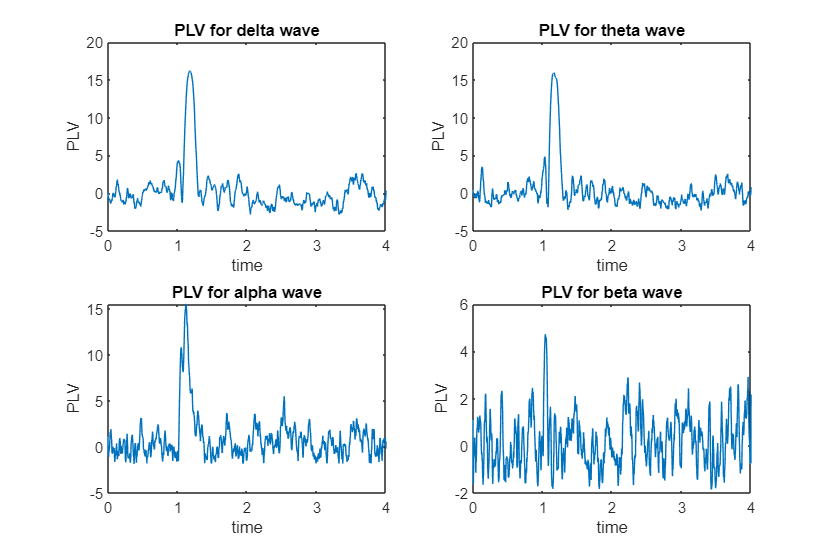

waveBounds = ["delta", "theta", "alpha", "beta"];
waveStart  = [0.1, 4, 8, 16];
waveEnd    = [4, 7, 15, 31];
PLV        = nan(length(waveBounds), length(t));
smoothPLV  = nan(length(waveBounds), length(t));
figure('Position', [10 10 900 600])
for i = 1:length(waveBounds)
    bpfilter = designfilt('bandpassfir','FilterOrder',100, ...
             'CutoffFrequency1',waveStart(i),'CutoffFrequency2',waveEnd(i), ...
             'SampleRate', SR);
    V4filtered = filtfilt(bpfilter, V4data);
    FEFfiltered = filtfilt(bpfilter, FEFdata);
    
    V4hilbert = angle(hilbert(V4filtered));
    FEFhilbert = angle(hilbert(FEFfiltered));
    % Calculating Phase Difference (PLV)
    PLV(i, :) = abs(sum(exp(1i * (V4hilbert - FEFhilbert)), 2)) / size(FEFdata, 2);
    PLV(i, :) = (PLV(i, :) - mean(PLV(i, 1:1000))) / std(PLV(i, 1:1000));
    subplot(2, 2, i)
    plot(t, PLV(i, :))
    xlabel('time')
    ylabel('PLV')
    title(strcat("PLV for " , waveBounds(i) , " wave"))
end

**(e)**

**Permutation Test: **For this section I have used permutation test for finding wheter there is a significancy in connectivity strength or not. For implementing this test, I have set number of permutation to 1000 and used circular shift for deriving new PLV for each sample. After that by using Kolmogorov-Smirnov (eCDF) test, it shows that by %5 significancy level it can be rejected that this value of PLV is significant so we can say that we have significancy of this PLV with %5 level.

**Rayleigh test: **As I read in publications, this test comes from circularity uniformly distributed around a direction. Von Mises distribution is described as the circular analouge of the normal distribution. Rayleigh test is a parametric test, and its original deviation involved the assumption that if there was a deviation from uniformity, that deviation would be of the von Mises form.

numPermutation = 1000;
maxIdxPLV = nan(1, 4);
for i = 1:size(PLV, 1)
    maxIdxPLV(i) = find(PLV(i, :) == max(PLV(i, :)));
end

newPLV = nan(length(waveBounds), length(t));
timePLV = nan(length(waveBounds), numPermutation);

for i = 1:numPermutation
    disp(i)
    randNum = randi([1 4000], 1);
    V4data = circshift(V4data, randNum);
    for j = 1:length(waveBounds)
        bpfilter = designfilt('bandpassfir','FilterOrder',100, ...
                 'CutoffFrequency1',waveStart(j),'CutoffFrequency2',waveEnd(j), ...
                 'SampleRate', SR);
        V4filtered = filtfilt(bpfilter, V4data);
        FEFfiltered = filtfilt(bpfilter, FEFdata);
        
        V4hilbert = angle(hilbert(V4filtered));
        FEFhilbert = angle(hilbert(FEFfiltered));
        % Calculating Phase Difference (PLV)
        newPLV(i, :) = abs(sum(exp(1i * (V4hilbert - FEFhilbert)), 2)) / size(FEFdata, 2);
        newPLV(i, :) = (newPLV(i, :) - mean(newPLV(i, 1:1000))) / std(newPLV(i, 1:1000));
        timePLV(j, i) = newPLV(i, maxIdxPLV(j));
    end
end

maxPLVs = nan(1, 4);
for i = 1:size(PLV, 1)
    maxPLVs(i) = max(PLV(i, :));
end

pValDelta = length(find(timePLV(1,:) > maxPLVs(1))) / numPermutation;
pValTheta = length(find(timePLV(2,:) > maxPLVs(2))) / numPermutation;
pValBeta  = length(find(timePLV(3,:) > maxPLVs(3))) / numPermutation;
pValAlpha = length(find(timePLV(4,:) > maxPLVs(4))) / numPermutation;
disp(["p-value of delta bound is: ", string(pValDelta)])

    "p-value of delta bound is: "    "0.013"



disp(["p-value of theta bound is: ", string(pValTheta)])

    "p-value of theta bound is: "    "0.009"



disp(["p-value of beta bound is: ", string(pValBeta)])

    "p-value of beta bound is: "    "0.006"



disp(["p-value of alpha bound is: ", string(pValAlpha)])

    "p-value of alpha bound is: "    "0.005"



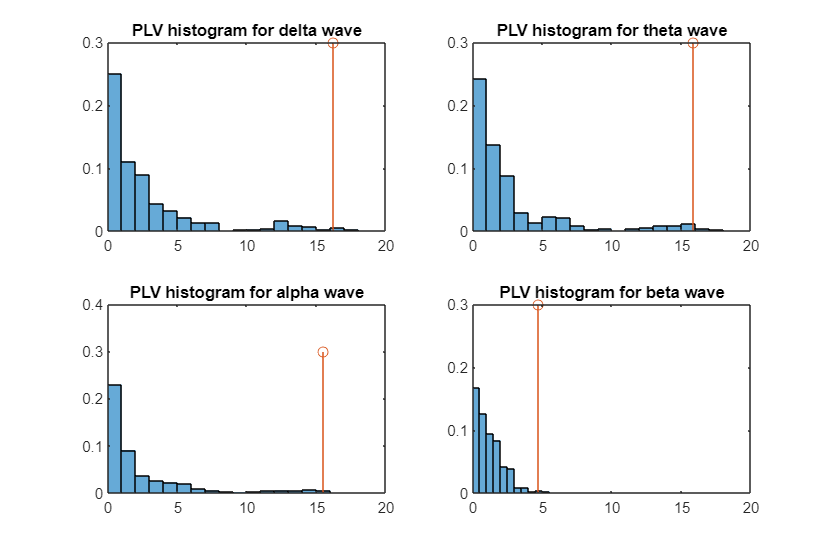


figure('Position', [10 10 900 600])
for i = 1:length(waveBounds)
    subplot(2, 2, i)
    histogram(timePLV(i,:), 'Normalization','probability')
    hold on
    stem(maxPLVs(i), 0.3)
    xlim([0 20])
    title(strcat("PLV histogram for " , waveBounds(i) , " wave"))
end

### **2.2 Linear Granger Causality (LGC) Analysis**  

**(a)**

Some assumptions that can be used in using LGC methods are mentioned below:

**(i)** Time serie data should be stationary time serie.

**(ii)** Trials should be independent.

#### **(b)** 

For testing stationarity of these time series, I have used kpss test for stationarity. In this test if p-value become under zero we can say that data is non-stationary but all p-values for every trials became more than 0.05 which is our significancy level so we can conclude that our data is stationary.

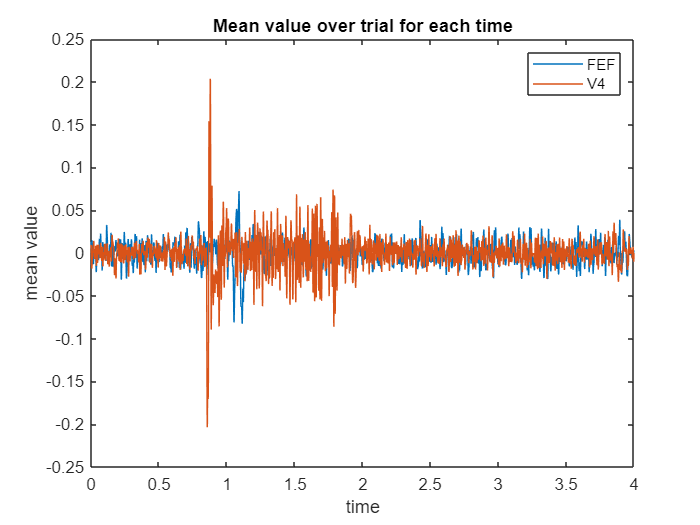

FEFmean = mean(FEFdata, 2)';
V4mean  = mean(V4data, 2)';
figure
plot(t, FEFmean, t, V4mean)
xlabel('time')
ylabel('mean value')
title('Mean value over trial for each time')
legend('FEF', 'V4')

rejectedFEF = 0;
rejectedV4  = 0;
stationaryresultsFEF = nan(size(FEFdata, 2), 1);
stationaryresultsV4  = nan(size(V4data, 2), 1);

for i = 1:size(FEFdata, 2)
    stationaryresultsFEF(i) = kpsstest(FEFdata(:, i));
    stationaryresultsV4(i)  = kpsstest(V4data(:, i));
    nonstationaryFEF        = find(stationaryresultsFEF == 1);
    nonstationaryV4         = find(stationaryresultsV4 == 1);
end

nonstationaryV4


nonstationaryV4 =

  0×1 empty double column vector



nonstationaryFEF


nonstationaryFEF =

  0×1 empty double column vector



### (c)

#### (i) Filtering

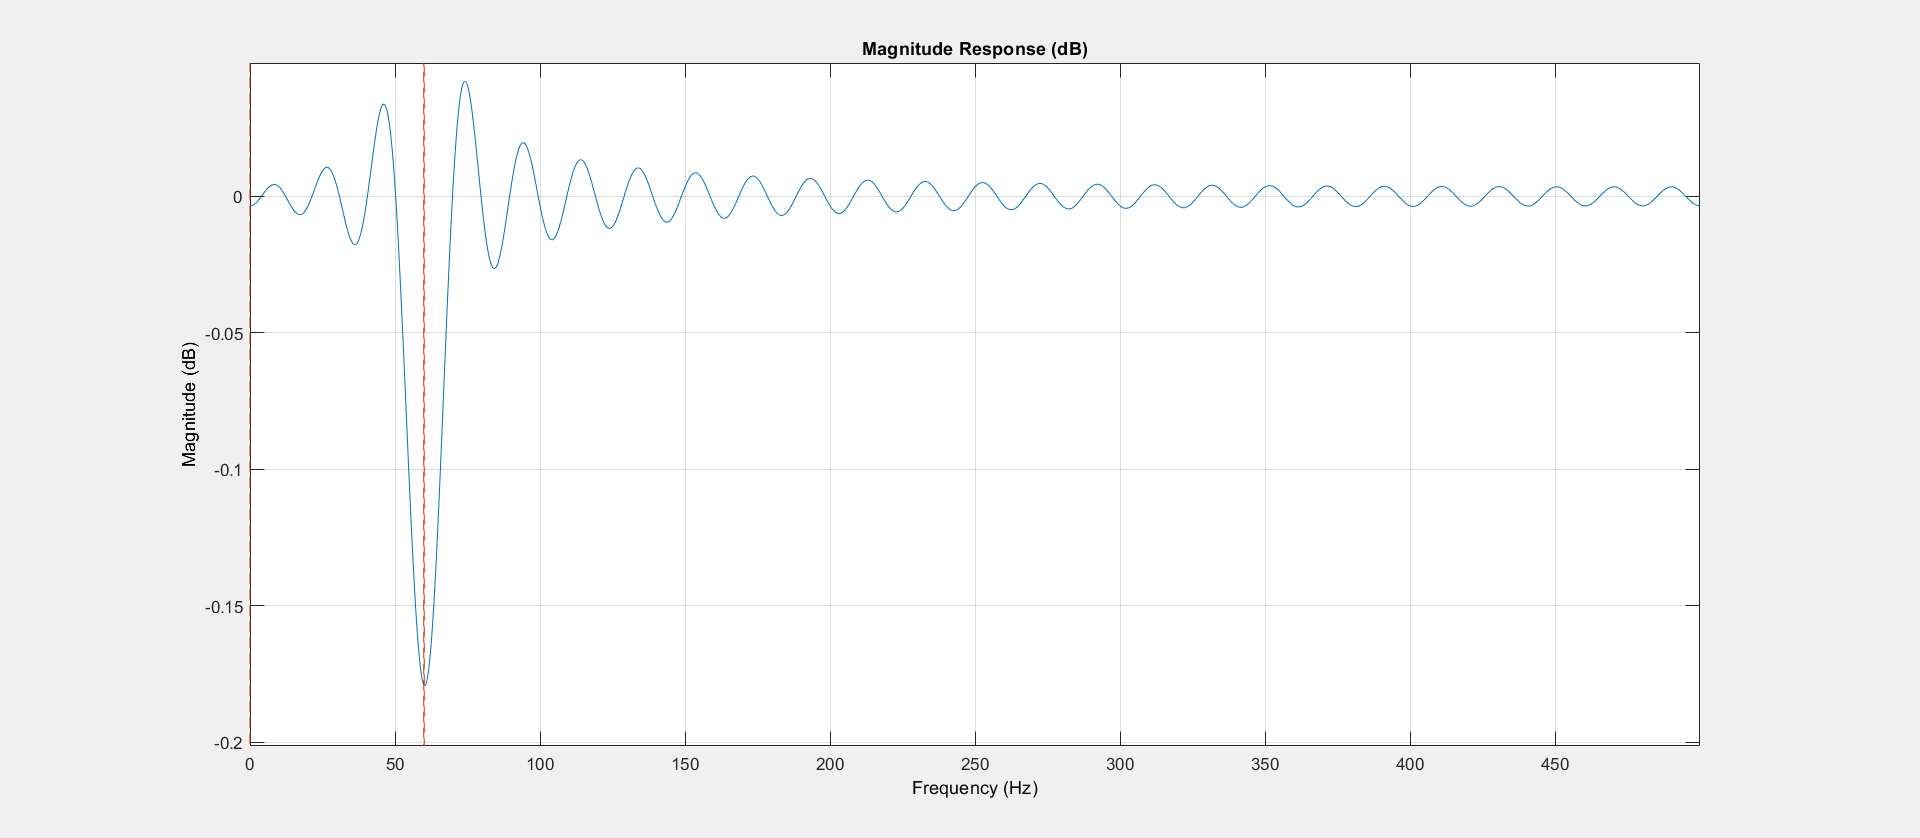

hpfilter = designfilt('highpassfir','FilterOrder',100,'CutoffFrequency',0.5,'StopbandAttenuation',65,'PassbandRipple',0.5,'SampleRate',SR);
fvtool(hpfilter)
V4filtered = filtfilt(hpfilter, V4data);
FEFfiltered = filtfilt(hpfilter, FEFdata);
notchfilter = designfilt('bandstopfir','FilterOrder',100,'CutoffFrequency1',59.9,'CutoffFrequency2',60.1,'PassbandRipple1',2,'StopbandAttenuation',65,'PassbandRipple2',2,'SampleRate',SR);
fvtool(notchfilter)

FEFnotched  = filtfilt(notchfilter, FEFfiltered);
V4notched  = filtfilt(notchfilter, V4filtered);

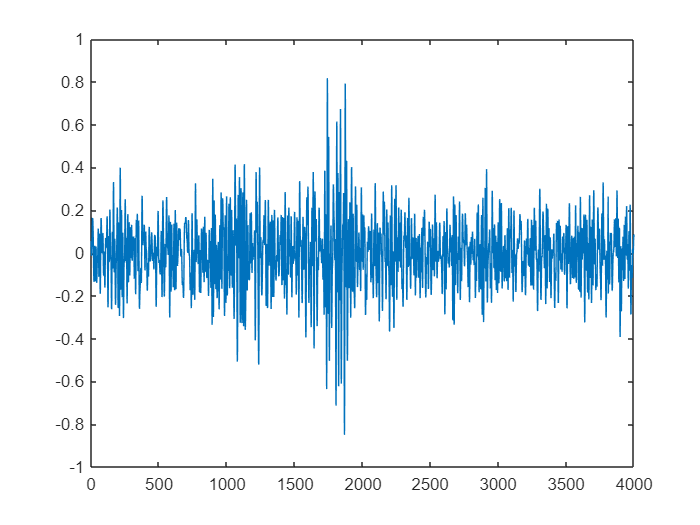

figure
plot(V4filtered(:, 1))

#### (ii) Normalization

numTrials = size(FEFdata, 2);
FEFnorm   = nan(size(FEFdata));
V4norm    = nan(size(V4data));
for i = 1:numTrials
    FEFnorm(:, i) = (FEFdata(:, i) - mean(FEFdata(:, i))) / std(FEFdata(:, i));
    V4norm(:, i)  = (V4data(:, i) - mean(V4data(:, i))) / std(V4data(:, i));
end


#### (iii) Differentiation

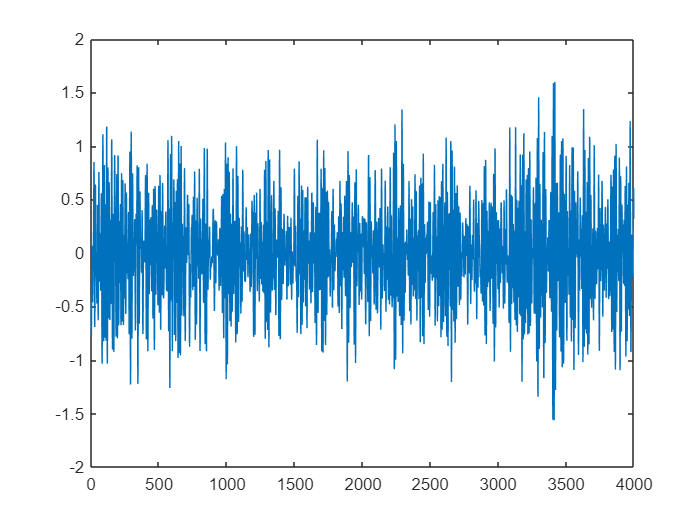

FEFdiff  = diff(FEFnorm, 1, 1);
V4diff   = diff(V4norm, 1, 1);
datadiff = nan(2, size(FEFdiff, 1), size(FEFdata, 2));
datadiff(1, :, :) = FEFdiff;
datadiff(2, :, :) = V4diff;

plot(FEFdiff(:, 1))

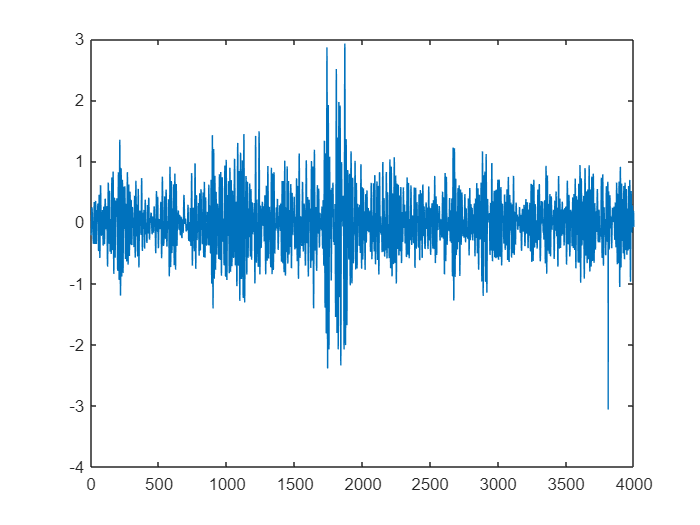

figure
plot(V4diff(:, 1))

### (d)

First step I imported data to EEGLAB to import it in fieldtrip. Then for evaluating this import, I plot time serie of first trial.

cfg = [];
cfg.dataset = 'data/datadiff.set';
ft_data1 = ft_preprocessing(cfg);

reading and preprocessing trial 196 from 196

the call to "ft_preprocessing" took 8 seconds


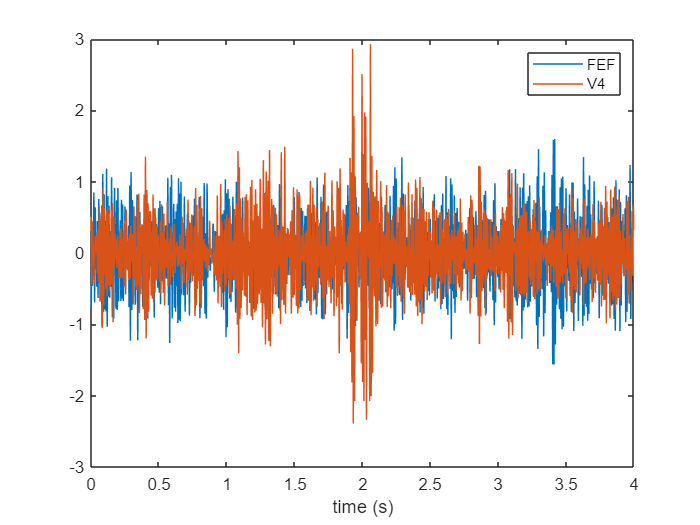

ft_data1.label = {'FEF', 'V4'};
%% Plot data to check
plot(ft_data1.time{1}, ft_data1.trial{1})
legend(ft_data1.label)
xlabel('time (s)')

### Compute frequency of time signals

For evaluating connectivity with fieldtrip, we should calculate frequency domain of signals. In fieldtrip this transformation can be done by using *mtmfft *which calculates FFT of signal. Power spectrum of first two trials for FEF and V4 can be shown as below.

cfg = [];
cfg.method    = 'mtmfft';
cfg.output    = 'fourier';
cfg.foilim    = [0 200];
cfg.tapsmofrq = 5;
freq          = ft_freqanalysis(cfg, ft_data1);
fd            = ft_freqdescriptives(cfg, freq);

the input is freq data with 2 channels, 801 frequencybins and no timebins
the call to "ft_selectdata" took 0 seconds
the call to "ft_freqdescriptives" took 1 seconds


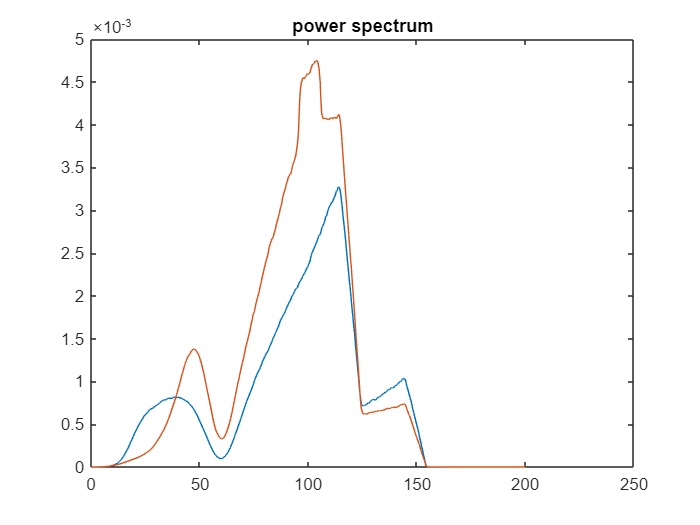


figure;plot(fd.freq, fd.powspctrm);
set(findobj(gcf,'color',[0 0.5 0]), 'color', [1 0 0]);
title('power spectrum');

#### Compute connectivity

For this section, I used *granger *and *coherence *functions of FieldTrip. The connectivity result between each cortexes can be shown as below. As you can see, we have two connectivity strength from V4 to FEF which can not be seen in oposite direction.


cfg = [];
cfg.method = 'granger';
g = ft_connectivityanalysis(cfg, freq);

the call to "ft_selectdata" took 0 seconds
computing multivariate non-parametric spectral factorization on 2 channels
the call to "ft_connectivityanalysis" took 5 seconds


cfg.method = 'coh';
c = ft_connectivityanalysis(cfg, freq);

the call to "ft_selectdata" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_connectivityanalysis" took 7 seconds


the call to "ft_selectdata" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_connectivityplot" took 1 seconds


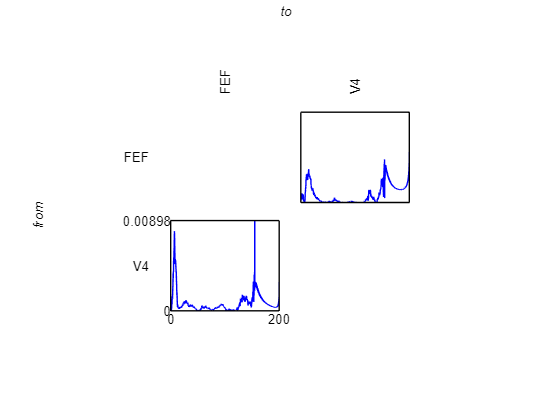

% visualize the results
cfg = [];
cfg.parameter = 'grangerspctrm';
figure; ft_connectivityplot(cfg, g);

### (e)

Some tests such as Kolmogorov-Smirnov can be implemented to argue about connectivity strength of each cortexes.

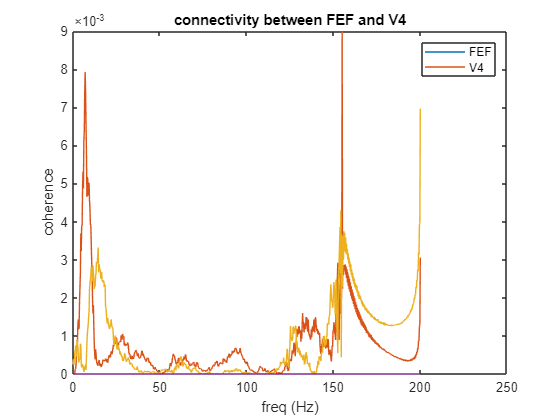

figure
plot(g.freq, squeeze(g.grangerspctrm(:,1,:)), g.freq, squeeze(g.grangerspctrm(:,2,:)))
title(sprintf('connectivity between %s and %s', g.label{1}, g.label{2}));
xlabel('freq (Hz)')
ylabel('coherence')
legend(g.label)